m = 1500

m = 1500

b = 60

b = 60

A = [0,1;0,-b/m]

A =          0    1.0000
         0   -0.0400


B = [0;1/m]

B = 1.0e-03 *

         0
    0.6667


C = [0,1]

C =      0     1


D = 0

D = 0

sys = ss(A,750*B,C,D)


sys =
 
  A = 
          x1     x2
   x1      0      1
   x2      0  -0.04
 
  B = 
        u1
   x1    0
   x2  0.5
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


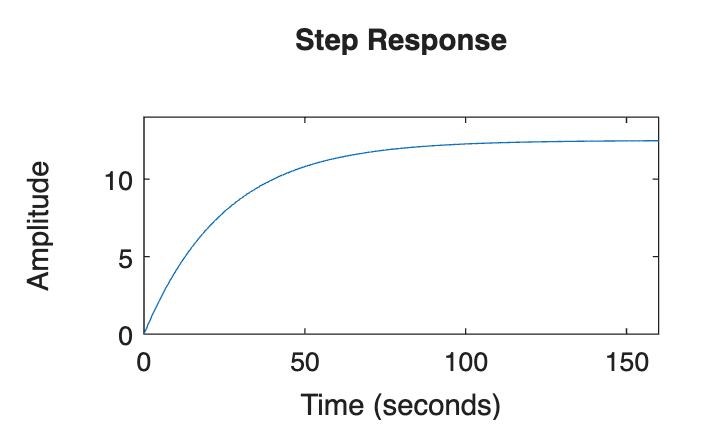

step(sys)


$$F = ma \ne \sin \omega t$$



$$\sin \frac{1}{2}$$



%To compare Ex 2.1(p48)
G = tf(1/m,[1,b/m])


G =
 
  0.0006667
  ---------
  s + 0.04
 
Continuous-time transfer function.


s = tf('s')


s =
 
  s
 
Continuous-time transfer function.


G1 = (1/m)/(s+b/m)


G1 =
 
  0.0006667
  ---------
  s + 0.04
 
Continuous-time transfer function.


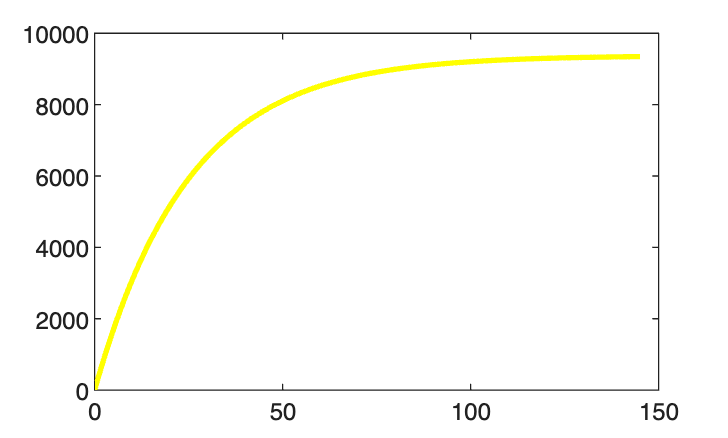


%Calculate step response

[ys,ts] = step(sys);
[yg,tg] = step(G1);


figure(1)
plot(ts,750*ys, 'y', 'LineWidth',2,'DisplayName','state-space')

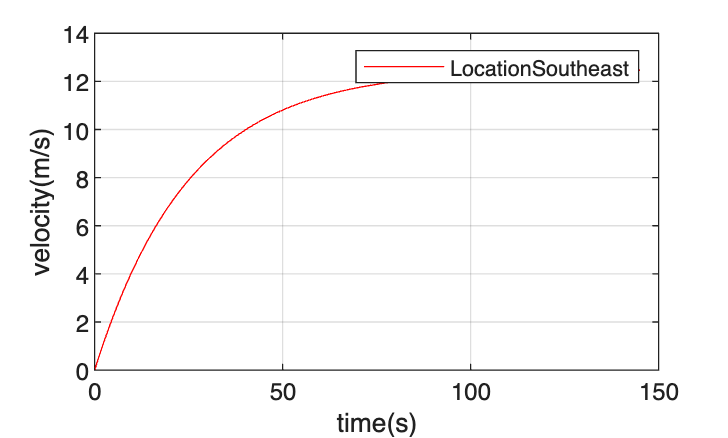

plot(tg,750*yg,'r-','DisplayName','Transfer-Function')
xlabel('time(s)')
ylabel('velocity(m/s)')
hold off
grid on
legend('LocationSoutheast')